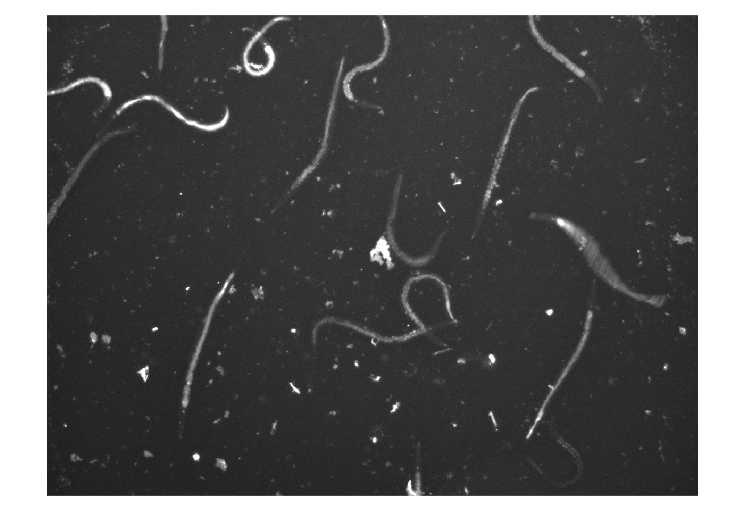

% Input data
img_gfp = imread("D:\AstraZeneca\Pilot_set2_odd_22h\221223_091848_Plate 1\GFP\A6_01_2_1_GFP_001.tif");
imshow(img_gfp)

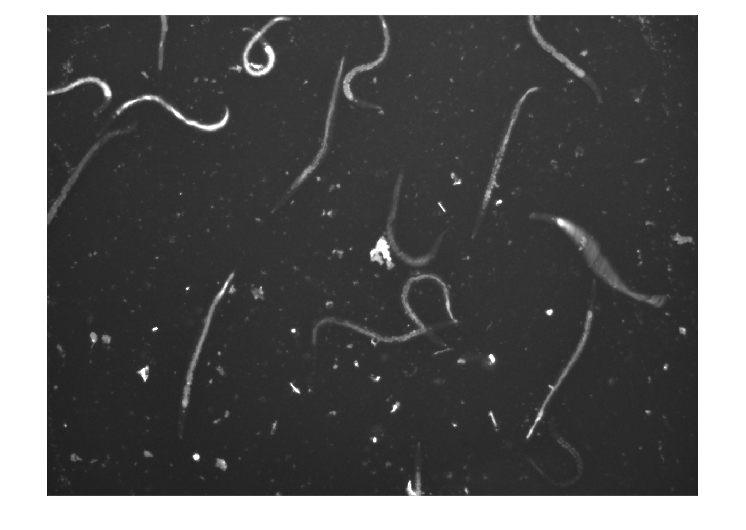

% First, find the worms by using wormArea function

%% Reduce noise
X = medfilt2(img_gfp);
imshow(X)

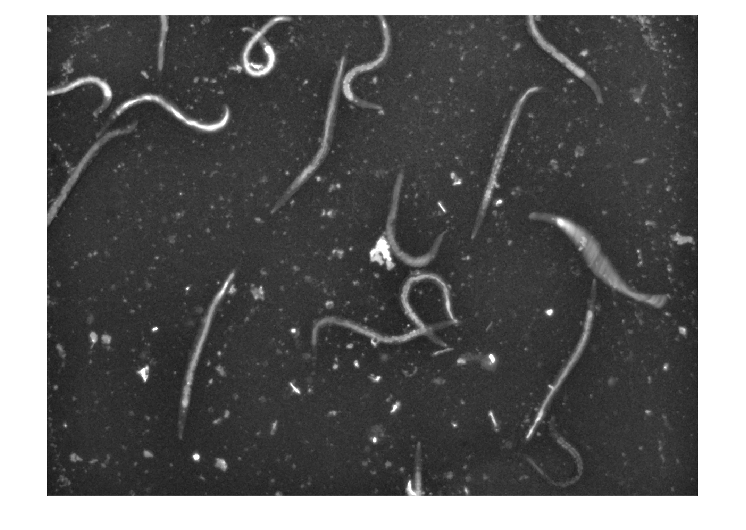

%% Adjust data to span data range.
X = adapthisteq(X);
imshow(X)

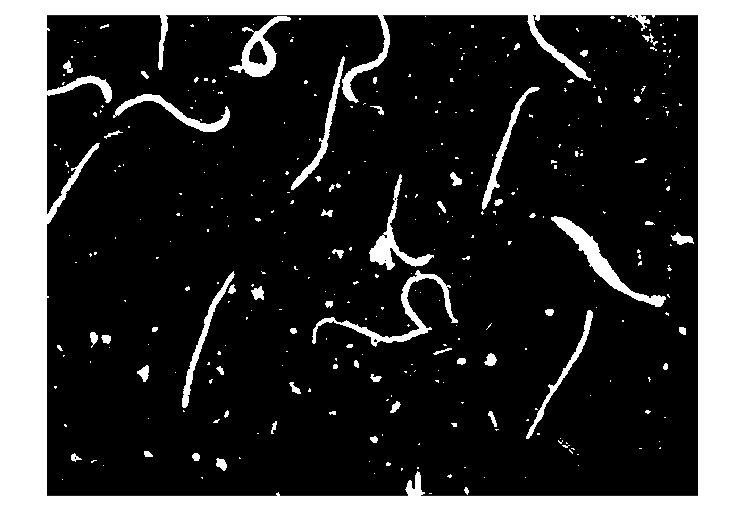

%% Threshold image - GLOBAL threshold
BW = imbinarize(X);
imshow(BW)

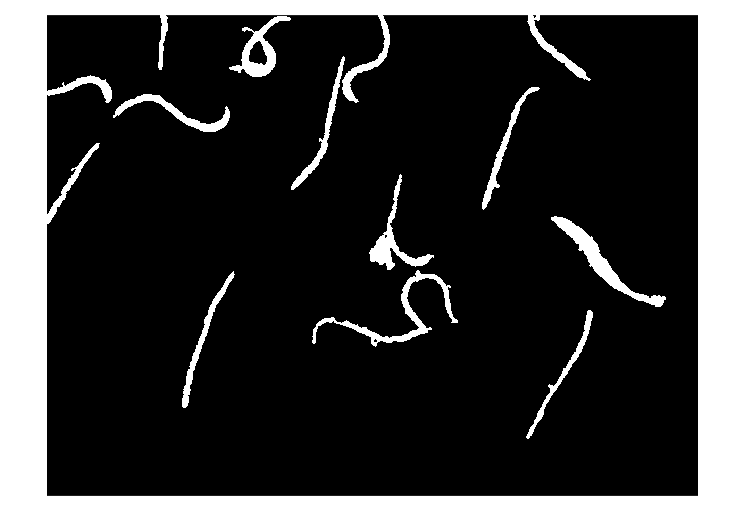

%% Close mask with disk
radius = 1;
decomposition = 0;
se = strel('disk', radius, decomposition);
BW = imclose(BW, se);

%% Open mask with disk
radius = 1;
decomposition = 0;
se = strel('disk', radius, decomposition);
BW = imopen(BW, se);

%% Input for region filtering
BW_out = BW;

%% Filter image based on image properties.
BW_out = bwpropfilt(BW_out,'Area',[1000, 50000]);
imshow(BW_out)

% Get properties
Area = []; %% not needed
properties = regionprops(BW_out, {'Area'});
properties = struct2table(properties);
Area = [Area; properties.Area];
Area;

% Create masked image
maskedImage = img_dmso;
maskedImage(~BW_out) = 0;

% Calculate worm area
nPixValues = sum(maskedImage(:)); %% not needed
nPix = nnz(maskedImage);

% Find the number of area identified in region properties
[~, numRegions] = bwlabel(BW_out);
numRegions;

% Threshold for GFP
BW_GFP = maskedImage > 10000;
BW_GFP_out = bwpropfilt(BW_GFP,'Area',[1000, 50000]);

% Get properties
[~, numRegions_GFP] = bwlabel(BW_GFP);
numRegions_GFP;

% Ratio
numRegions/numRegions_GFP